# ---- ESTABLISHING COMMUNICATION ----

port = "COM10";      
baud = 115200;
outfile = "samples.csv";

% ---- OPEN SERIAL ----

s = serialport(port, baud);
configureTerminator(s, "LF");

disp("Waiting for START...");

Waiting for START...



data = [];
recording = false;

while true
    line = readline(s);
    line = strtrim(line);

    if line == "START"
        disp("Recording started");
        recording = true;
        continue
    end

    if line == "END"
        disp("Recording ended");
        break
    end

    if recording
        val = str2double(line);
        if ~isnan(val)
            data(end+1) = val; %#ok<AGROW>
        end
    end
end

Recording started


Recording ended



% ---- SAVE TO CSV ----
writematrix(data', outfile);
disp("Saved to samples.csv");

Saved to samples.csv


## ---- READING AND HANDLING THE SIGNAL ----

signal = readmatrix("samples.csv");
fs = 8000;       % Sampling frequency
audio = signal;

%% Time Axis
t = (0:length(audio)-1) / fs;

%% FFT Parameters
Nfft = 4096;
window = hann(Nfft);

%% Select Short Frame (quasi-stationary)
frame = audio(1:Nfft) .* window;

%% FFT
X = fft(frame, Nfft);
X = abs(X(1:Nfft/2+1));              % One-sided magnitude
f = (0:Nfft/2) * fs / Nfft;

%% Normalize Spectrum
X = X / max(X);
X_db = 20*log10(X + eps);

%% ---- Band-pass for 300-3400 Hz ----
f_low = 300;
f_high = 3400;

% Indices within desired frequency band
band_idx = (f >= f_low) & (f <= f_high);

% Filter frequency and spectrum
f_band = f(band_idx);
X_db_band = X_db(band_idx);

%% Peak Detection within band
[pks, locs_idx] = findpeaks(X_db_band, f_band, ...
    "MinPeakHeight", -40, ...
    "MinPeakDistance", 40);


## ---- PLOTS ----

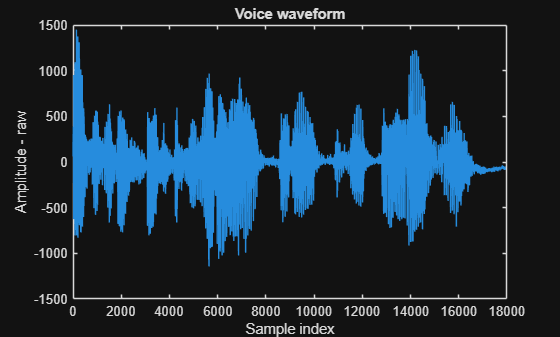


figure

% Raw data
plot(data);
xlabel("Sample index");
ylabel("Amplitude - raw");
title("Voice waveform");

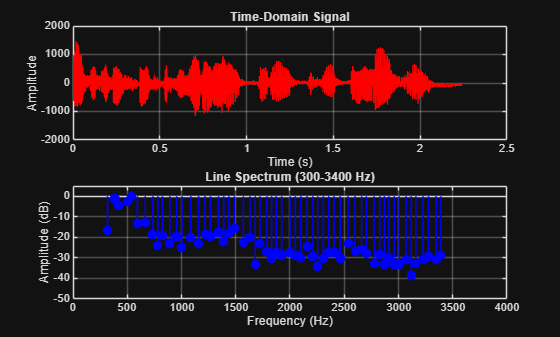


% Time-domain signal
subplot(2,1,1)
plot(t, audio, 'r', 'LineWidth', 1)
grid on
xlabel("Time (s)")
ylabel("Amplitude")
title("Time-Domain Signal")
ylim([-2000 2000])

% Line spectrum (300-3400 Hz)
subplot(2,1,2)
stem(locs_idx, pks, 'b', 'filled', 'LineWidth', 1.2)
grid on
xlabel("Frequency (Hz)")
ylabel("Amplitude (dB)")
title("Line Spectrum (300-3400 Hz)")
ylim([-50 5])
xlim([0 4000])

## ---- FEATURE EXTRACTION ----

% ---- Select analysis frame ----
frameLen = 2048;
frame1 = audio(1:frameLen);
frame1 = frame1 - mean(frame1);         % DC removal
frame1 = frame1 .* hann(frameLen);     % Windowing

%% 1. Fundamental Frequency (F0)
r = xcorr(frame1);
r = r(frameLen:end);                 % positive lags only

minLag = floor(fs/400);              % 400 Hz
maxLag = floor(fs/50);               % 50 Hz

[~, idx] = max(r(minLag:maxLag));
lag = idx + minLag - 1;
f0 = fs / lag;

X1 = fft(frame1, Nfft);
mag = abs(X1(1:Nfft/2+1));             % Linear magnitude

%% 2. RMS Energy
rmsVal = sqrt(mean(frame1.^2));

%% 3. Spectral Centroid
mag = mag(:);   % force column
f = f(:);       % force column

centroid = sum(f .* mag) / sum(mag);

%% 4. Zero-Crossing Rate
zcr = sum(abs(diff(frame1 > 0))) / length(frame1);

% Adaptive thresholds (robust for speech)
energyThresh = 0.02 * max(abs(audio));    % relative to signal level
zcrThresh = 0.15;                         % typical speech threshold

## ---- FRAME TYPE DETECTION ----

%% Decision logic

energyDB = 20*log10(rmsVal + 1e-12);

if energyDB < -40
    speechType = "SILENCE";
    return
end

r = xcorr(frame1);
r = r(length(frame1):end);

minLag = floor(fs/400);
maxLag = floor(fs/50);

[rPeak, idx] = max(r(minLag:maxLag));
peakStrength = rPeak / r(1);

band = (f >= 300 & f <= 3400);
magBand = mag(band) + 1e-12;

flatness = exp(mean(log(magBand))) / mean(magBand);

%% ---- Classification ----
if peakStrength > 0.20 && flatness < 0.50
    speechType = "VOICED";
else
    speechType = "SILENCE";
end

## ---- Displaying Results and sending to OLED ----

if speechType ~= "VOICED"
    f0 = NaN;
end

disp("Speech Type: " + speechType);

Speech Type: VOICED



if isnan(f0)
    disp("Fundamental Frequency (F0): not calculated, frame is not VOICED");
else
    disp("Fundamental Frequency (F0): " + f0 + " Hz");
end

Fundamental Frequency (F0): 123.0769 Hz



disp("RMS Energy: " + rmsVal);

RMS Energy: 119.966


Spectral Centroid: 785.6259 Hz


disp("Zero-Crossing Rate: " + zcr);

Zero-Crossing Rate: 0.10059


disp("Spectral Centroid: " + centroid + " Hz");


## ---- Send to MCU ----

if isnan(f0)
    f0_str = "NaN";
else
    f0_str = sprintf("%.1f", f0);
end

msg = sprintf( ...
    "F0,%s,RMSENERGY,%.2f,ZCR,%.3f,CENTROID,%.0f,TYPE,%s\n", ...
    f0_str, rmsVal, zcr, centroid, speechType);

write(s, msg, "string");
disp("Sent: " + msg);

Sent: F0,123.1,RMSENERGY,119.97,ZCR,0.101,CENTROID,786,TYPE,VOICED

